# A DFS Implementation in MATLAB

The DFS search algorithm starts with a very simple heuristic: search the latest found path first. The DFS algorithm is built within a class dfsCls in this repo, and is applicable to different problems.

By code structure, it requires the existence of a problem class object obj.problem that has the  following:

    1. A property called `action_space`, which contains all actions

    2. A method called `transition`(), which produces next states

## Demonstration with the Maze example

The maze problem is adopted from [Rodney Meyer's maze implementation](https://www.mathworks.com/matlabcentral/fileexchange/6705-maze) on MATLAB Central, and the maze definition is modified into a class definition `mazeCls`.

A 10x10 maze can be constructed using:

mz = mazeCls(10,10,'c');

Then a DFS object can be associated with the maze object using:

dfsObj = dfsCls(mz);

By default, the starting and goal points in the maze are:

start = [1,1];
goal = [10,10];

Supply the start and goal points to the `dfs`() function, we can obtain the action history that successfully leads to the goal from the start:

action_hist = dfsObj.dfs(start,goal);

We can visualize the result of the DFS found path by calling the `show_maze`() and `show_path`() functions built into the `mazeCls` class:

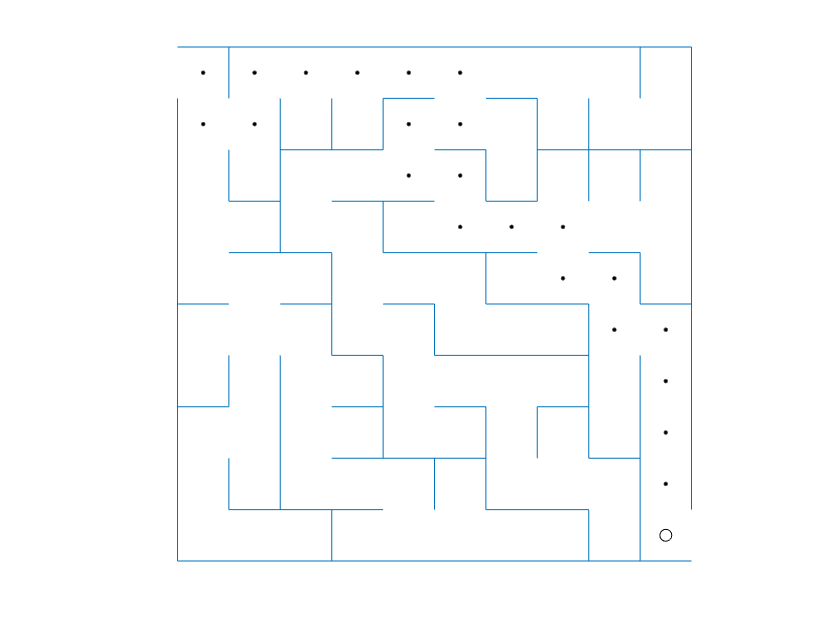

% visualize the path
h=figure();
dfsObj.problem.show_maze(h);
dfsObj.problem.show_path(action_hist,h);